# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 4;
threshold = 0.6;

## Generate a random physical topology

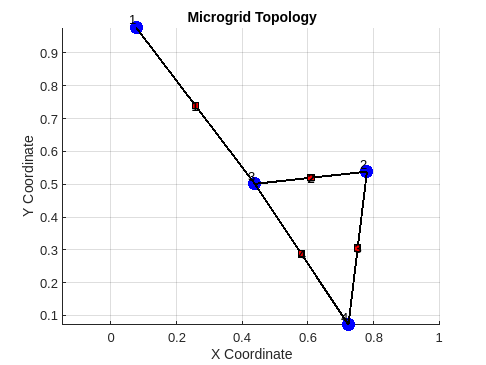

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
     1     1     0     1
     0     1     1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold);


%%%% Update the figure to show the assumed initial communication topology
% (A_ij matrix representa the communication topology)



## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.22;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance
IL0 = 5;        % Constant Current Load
LoadNoiseMean = 10;
LoadNoiseStd = 2;


for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,IL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 2;     % Line Resistance
Ll0 = 0.01;     % Line Inductance

numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 
 % global DG Line B_il A_ij % Making some values as global variables

## Co-Design Process

parameters

BarGamma = 1000000;    % Fixed value for gammaBar
isSoft = 1;      % Set to 1 to avoid the hard graph constraint

% pScalar = 1/(numOfDGs+numOfLines);
piScalar = 10^0;
plScalar = 10^0;

piVals = piScalar*ones(1,numOfDGs);
plVals = plScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

% Inside the function, you need to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

First Method: This Method computes the passivity indices for DGs and lines at the same time. 

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

Constraint "W_2" is satisfied by -4.3047e-09 .


W_val = 1.0e+05 *

    0.0000         0         0    0.0000    0.0000   -0.0000         0         0         0
         0    0.0000         0    0.0000    0.0000   -0.0000         0         0         0
         0         0    0.0000   -0.0000   -0.0000    0.0000         0         0         0
    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    2.9537   -0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0000    0.0000   -0.0000    0.0001         0         0
         0         0         0    0.0000    0.0000   -0.0000         0    0.0001         0
         0         0         0   -0.0000   -0.0000   -0.0000         0         0    0.0001


Constraint "W_4" is satisfied by -3.0591e-09 .


W_val = 1.0e+05 *

    0.0000         0         0    0.0000    0.0000   -0.0000         0         0         0
         0    0.0000         0    0.0000    0.0000   -0.0000         0         0         0
         0         0    0.0000   -0.0000   -0.0000    0.0000         0         0         0
    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    2.9523   -0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0000    0.0000   -0.0000    0.0001         0         0
         0         0         0    0.0000    0.0000   -0.0000         0    0.0001         0
         0         0         0   -0.0000   -0.0000   -0.0000         0         0    0.0001


Constraint "W_1" is satisfied by -2.9245e-09 .


W_val = 1.0e+05 *

    0.0000         0         0    0.0000    0.0000   -0.0000         0         0         0
         0    0.0000         0    0.0000    0.0000   -0.0000         0         0         0
         0         0    0.0000   -0.0000   -0.0000    0.0000         0         0         0
    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    2.9863   -0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0000    0.0000   -0.0000    0.0001         0         0
         0         0         0    0.0000    0.0000   -0.0000         0    0.0001         0
         0         0         0   -0.0000   -0.0000   -0.0000         0         0    0.0001


Constraint "W_3" is satisfied by 3.0733e-09 .


W_val = 1.0e+05 *

    0.0000         0         0    0.0000    0.0000   -0.0000         0         0         0
         0    0.0000         0    0.0000    0.0000   -0.0000         0         0         0
         0         0    0.0000   -0.0000   -0.0000    0.0000         0         0         0
    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    3.2667   -0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0000    0.0000   -0.0000    0.0001         0         0
         0         0         0    0.0000    0.0000   -0.0000         0    0.0001         0
         0         0         0   -0.0000   -0.0000   -0.0000         0         0    0.0001


Constraint "WBar_2" is satisfied by 5.1789e-07 .


W_val =   266.1591 -132.9445
 -132.9445   66.4060


Constraint "WBar_3" is satisfied by 5.7768e-07 .


W_val =   266.1569 -132.8323
 -132.8323   66.2946


Constraint "WBar_1" is satisfied by 5.9089e-07 .


W_val =   256.5946 -127.8708
 -127.8708   63.7241


Constraint "WBar_4" is satisfied by 6.481e-07 .


W_val =   262.9914 -131.2577
 -131.2577   65.5113


Constraint "rhoBar_2_low1_2" is satisfied by 4.8975e-06 .


W_val = 268.1655

Constraint "rhoBar_3_low1_2" is satisfied by 5.225e-06 .


W_val = 268.1655

Constraint "rhoBar_1_low1_1" is satisfied by 5.394e-06 .


W_val = 258.6061

Constraint "rhoBar_4_low1_4" is satisfied by 5.7298e-06 .


W_val = 265.0037

Constraint "nuBar_2_low1_2" is satisfied by 1.1852e-05 .


W_val = -66.4060

Constraint "P_3" is satisfied by 1.6254e-05 .


W_val =     0.2258    0.6610   -0.0934
    0.6610    2.1640   -0.2994
   -0.0934   -0.2994    0.0426


Constraint "P_2" is satisfied by 1.7121e-05 .


W_val =     0.2173    0.6530   -0.0893
    0.6530    2.1874   -0.2934
   -0.0893   -0.2934    0.0405


Constraint "P_4" is satisfied by 1.7527e-05 .


W_val =     0.2213    0.6577   -0.0911
    0.6577    2.1815   -0.2959
   -0.0911   -0.2959    0.0413


Constraint "P_1" is satisfied by 1.791e-05 .


W_val =     0.2252    0.6625   -0.0929
    0.6625    2.1780   -0.2992
   -0.0929   -0.2992    0.0423


Constraint "nuBar_3_low1_4" is satisfied by 1.9281e-05 .


W_val = -66.2946

Constraint "nuBar_1_low1_1" is satisfied by 1.9868e-05 .


W_val = -63.7241

Constraint "nuBar_2_low1_3" is satisfied by 7.5591e-05 .


W_val = -66.4061

Constraint "nu_3_low" is satisfied by 0.00090184 .


W_val = -12.5222

Constraint "nu_1_low" is satisfied by 0.00093338 .


W_val = -12.5949

Constraint "nu_4_low" is satisfied by 0.0010051 .


W_val = -12.8427

Constraint "nu_2_low" is satisfied by 0.0010735 .


W_val = -13.0878

Constraint "rhoTilde_1_high1" is satisfied by 0.062724 .


W_val = 1

Constraint "rhoTilde_4_high1" is satisfied by 0.065295 .


W_val = 1

Constraint "rhoTilde_2_high1" is satisfied by 0.065406 .


W_val = 1

Constraint "rhoTilde_3_high1" is satisfied by 0.065406 .


W_val = 1

Constraint "nuBar_3_low1_2" is satisfied by 0.11143 .


W_val = -66.4060

Constraint "nuBar_4_low1_4" is satisfied by 0.78327 .


W_val = -66.2946

Constraint "nuBar_4_low1_3" is satisfied by 0.89474 .


W_val = -66.4061

Constraint "rhoTilde_3_low" is satisfied by 0.93359 .


W_val = 0.9346

Constraint "rhoTilde_2_low" is satisfied by 0.93359 .


W_val = 0.9346

Constraint "rhoTilde_4_low" is satisfied by 0.93371 .


W_val = 0.9347

Constraint "rhoTilde_1_low" is satisfied by 0.93628 .


W_val = 0.9373

Constraint "rhoBar_1_low1_3" is satisfied by 1.3084 .


W_val = 257.2977

Constraint "PBar_1" is satisfied by 1.8832 .


W_val = 1.8842

Constraint "PBar_3" is satisfied by 1.9689 .


W_val = 1.9699

Constraint "PBar_2" is satisfied by 1.9883 .


W_val = 1.9893

Constraint "PBar_4" is satisfied by 2.4206 .


W_val = 2.4216

Constraint "nuBar_1_low1_3" is satisfied by 2.682 .


W_val = -66.4061

Constraint "rhoBar_3_low1_4" is satisfied by 3.1618 .


W_val = 265.0037

Constraint "rhoBar_4_low1_3" is satisfied by 7.7059 .


W_val = 257.2977

Constraint "rhoBar_2_low1_3" is satisfied by 10.8677 .


W_val = 257.2977

Constraint "nu_3_high" is satisfied by 12.5203 .


W_val = -12.5213

Constraint "gammaTilde_3_low" is satisfied by 12.5212 .


W_val = 12.5222

Constraint "nu_1_high" is satisfied by 12.5929 .


W_val = -12.5939

Constraint "gammaTilde_1_low" is satisfied by 12.5939 .


W_val = 12.5949

Constraint "nu_4_high" is satisfied by 12.8407 .


W_val = -12.8417

Constraint "gammaTilde_4_low" is satisfied by 12.8417 .


W_val = 12.8427

Constraint "nu_2_high" is satisfied by 13.0858 .


W_val = -13.0868

Constraint "gammaTilde_2_low" is satisfied by 13.0868 .


W_val = 13.0878

Constraint "rhoTilde_3_high2" is satisfied by 49.1542 .


W_val = 50.0888

Constraint "rhoTilde_1_high2" is satisfied by 49.4422 .


W_val = 50.3795

Constraint "rhoTilde_4_high2" is satisfied by 50.4362 .


W_val = 51.3709

Constraint "rhoTilde_2_high2" is satisfied by 51.4167 .


W_val = 52.3513

Constraint "nuBar_1_high" is satisfied by 63.7231 .


W_val = -63.7241

Constraint "nuBar_4_high" is satisfied by 65.5103 .


W_val = -65.5113

Constraint "nuBar_3_high" is satisfied by 66.2936 .


W_val = -66.2946

Constraint "nuBar_2_high" is satisfied by 66.405 .


W_val = -66.4060

Constraint "rhoBar_1_low2_1" is satisfied by 255.6838 .


W_val = 2.9222

Constraint "rhoBar_1_low2_3" is satisfied by 255.6895 .


W_val = 2.9166

Constraint "rhoBar_1low" is satisfied by 258.6051 .


W_val = 258.6061

Constraint "rhoBar_4_low2_4" is satisfied by 262.0709 .


W_val = 2.9328

Constraint "rhoBar_4_low2_3" is satisfied by 262.0871 .


W_val = 2.9166

Constraint "rhoBar_4low" is satisfied by 265.0027 .


W_val = 265.0037

Constraint "rhoBar_3_low2_4" is satisfied by 265.2327 .


W_val = 2.9328

Constraint "rhoBar_2_low2_3" is satisfied by 265.2489 .


W_val = 2.9166

Constraint "rhoBar_2_low2_2" is satisfied by 265.2594 .


W_val = 2.9061

Constraint "rhoBar_3_low2_2" is satisfied by 265.2594 .


W_val = 2.9061

Constraint "rhoBar_2low" is satisfied by 268.1645 .


W_val = 268.1655

Constraint "rhoBar_3low" is satisfied by 268.1645 .


W_val = 268.1655

Constraint "gammaTilde_2_high" is satisfied by 999986.9122 .


W_val = 13.0878

Constraint "gammaTilde_4_high" is satisfied by 999987.1573 .


W_val = 12.8427

Constraint "gammaTilde_1_high" is satisfied by 999987.4051 .


W_val = 12.5949

Constraint "gammaTilde_3_high" is satisfied by 999987.4778 .


W_val = 12.5222

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1


Second Method: This method first computes the DGs' passivity indices and use those properties to compute the Lines' passivity indices. 

% [DG, rhoTilde_i, nu_i, gammaTilde_i,statusDG] = designDGPassivity(DG, B_il,piVals);
% [Line, statusLine] = designLinePassivity(Line, DG, B_il, BarGamma, piVals,plVals,rhoTilde_i, nu_i);
%%%% Theoretically explain why this works in the paper, in a corollary (of Theorem 2).  
%%%% There is an imbalance


DG{1}

ans = struct with fields:
              R: 0.0227
              L: 0.0150
              C: 0.2207
              Y: 3.2464
             IL: 5.0381
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.0763 0.9780]
             P0: [3×3 double]
             K0: [9.0125e+03 -3.7196e+04 -2.4335e+05]
             nu: -12.5939
            rho: 1.0669
    gammaTilde0: 12.5949


Line{1}

ans = struct with fields:
      R: 2.0067
      L: 0.0147
      A: -136.7185
      B: 68.1314
     P0: 1.8842
     nu: -63.7241
    rho: 258.6061


## 2. Global Controller Design

% Initialized nominal and reference voltages
V_nom = 120;            % Nominal Voltage
V_ref = 48;             % Reference Voltage

% Scenario #1: Global Load Change
R_Global = 5;           % Global Load
ChangeGlobalLoad1 = 1;  % Connect Global Load #2
ChangeGlobalLoad2 = 3;  % Disconnect Global Load #2

% Scenario #2: Plug-and-Play 
PlugOut = 2;            % Plug out DG #4
PlugIn = 4;             % Plug in DG #4

% Scenario #3: Change of Reference Voltage:
V_ref1 = 48;
V_ref2 = 100;
change_reference = 4;


[DG,Line,statusGlobalController,gammaTildeVal,K,C,BarC,H,P_iVal,P_lVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

Linear matrix variable 24x24 (symmetric, real, 5 variables)
Coefficient range: 1 to 13.0868
Linear matrix variable 24x24 (symmetric, real, 149 variables)
Coefficient range: 0.038207 to 1.07
Linear matrix variable 16x16 (symmetric, real, 8 variables)
Coefficient range: 12.5213 to 268.1655
Constraint "W" is violated by -0.61803 .


W_val =     0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
         0         0         

Principal minor 21 is not positive semi-definite.
Principal minor 22 is not positive semi-definite.
Principal minor 24 is not positive semi-definite.
Principal minor 26 is not positive semi-definite.
Principal minor 28 is not positive semi-definite.
Constraint "W_Temp_3" is satisfied by -1e-09 .
Constraint "PBar_22" is satisfied by -1e-09 .
Constraint "PBar_44" is satisfied by -1e-09 .
Constraint "P_33" is satisfied by -1e-09 .
Constraint "PBar_33" is satisfied by -1e-09 .
Constraint "PBar_11" is satisfied by -1e-09 .
Constraint "W_Temp_1" is satisfied by -1e-09 .
Constraint "P_22" is satisfied by -1e-09 .
Constraint "P_44" is satisfied by -1e-09 .
Constraint "P_11" is satisfied by -1e-09 .
Constraint "W_Temp_1" is satisfied by -1e-09 .
Constraint "Q_Structure" is satisfied by -1.0368e-15 .
Constraint "gammaTilde_low" is satisfied by 6.9128e-10 .
Constraint "gammaTilde_high" is satisfied by 1000000 .


Mat_1Eigs = 1.0e-14 *

    0.2115
    0.2115
    0.2115
    0.3593
    0.3593
    0.3593
    0.3603
    0.3603
    0.3603
    0.6490


Mat_2Eigs = 1.0e-13 *

    0.0212
    0.0212
    0.0212
    0.0359
    0.0359
    0.0359
    0.0360
    0.0360
    0.0360
    0.0649


Mat_3Eigs =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Mat_4Eigs =    -0.6180
   -0.6180
   -0.6180
   -0.6180
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Mat_44Eigs = 1.0e-15 *

    0.2452
    0.2481
    0.3008
    0.3578
    0.3614
    0.3650
    0.3711
    0.4132
    0.4224
    0.6266


Mat_4_Test1Eigs = 1.0e-14 *

   -0.0548
   -0.0231
   -0.0217
   -0.0080
   -0.0055
    0.0118
    0.0150
    0.0158
    0.0159
    0.0161


Mat_4_Test2Eigs = 1.0e-13 *

   -0.1472
   -0.1340
   -0.0581
    0.0025
    0.0030
    0.0036
    0.0036
    0.0041
    0.0041
    0.0042


Mat_4_Test3Eigs =    -0.6180
   -0.6180
   -0.6180
   -0.6180
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


ans = 1.0e-15 *

    0.5153         0         0         0
         0    0.2754         0         0
         0         0    0.1689         0
         0         0         0    0.2798


ans = 1.0e-15 *

    0.1744         0         0         0
         0    0.1294         0         0
         0         0    0.1712         0
         0         0         0    0.1312


GammaMat =    12.5949         0         0         0
         0   13.0878         0         0
         0         0   12.5222         0
         0         0         0   12.8427


ans = 1.6913e-09

Mat_5Eigs =    -0.6180
   -0.6180
   -0.6180
   -0.6180
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Mat_55Eigs = 1.0e-13 *

    0.3470
    0.3478
    0.4509
    0.4590


Mat_5_Test1Eigs = 1.0e-13 *

   -0.1223
   -0.1145
   -0.0614
    0.0212
    0.0212
    0.0300
    0.0359
    0.0359
    0.0360
    0.0360


Mat_5_Test2Eigs = 1.0e-13 *

    0.0024
    0.0025
    0.0030
    0.0034
    0.0036
    0.0036
    0.0036
    0.0041
    0.0042
    0.0061


Mat_6Eigs =    -0.6180
   -0.6180
   -0.6180
   -0.6180
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusGlobalController = logical
   0


gammaTildeVal = 1.6913e-09

K = 4×4 cell array
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}


C =      1     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     1     0     0    -1     0     0     0     0     0
     0     0     0     1     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     1     0     0    -1     0     0


BarC =    -4.5315         0         0         0
         0         0         0         0
         0         0         0         0
         0   -4.5267   -4.5267         0
         0         0         0         0
         0         0         0         0
    4.5331    4.5331         0   -4.5331
         0         0         0         0
         0         0         0         0
         0         0    4.5427    4.5427


H =      0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1


P_iVal = 1.0e-15 *

    0.5153
    0.2754
    0.1689
    0.2798


P_lVal = 1.0e-15 *

    0.1744
    0.1294
    0.1712
    0.1312


%%%% Theoretically think about adding cormalizing constraints trace(P_i)==1, trace(P_l)==1 constraint

K{1,1}

ans =          0         0         0
         0   -0.2835         0
         0         0         0


K{4,4}

ans =          0         0         0
         0   -0.4399         0
         0         0         0



% AT the local controller, instead of adding xconstraints, what if we added
% them as soft constraints in the objective?
% SImilarly, we can bias the global controller design by selecting its
% objective

#### The following functions are desgined to evaluate the effects of different parameters on the passivity indices of DGs and lines and their feasibilities

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% See the 'OptimizepValsMethod1.m' file. 

Optimize pVals (Method 2: Use Matlab 'fmincon')

% [piVals, plVals] = optimizeCodesignParameters()

Optimize pVals (Method 3)

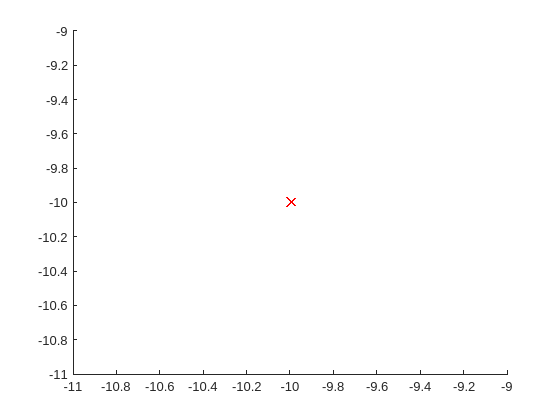

You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)


% plotLocalControlDesign(DG, Line, B_il, BarGamma, numOfDGs, numOfLines);
% hold on
% plotGlobalControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

plotCombinedControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

% plotTestBothFeasibility(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

Function to evaluate the effect of number of DGs and Threshold

% numDGsRange = 5:6;              % Example range for number of DGs
% thresholdRange = 0.1:0.1:1;     % Example range for threshold values
% pScalarRange = 0.01:0.01:10;    % Example range for pScalar values
% BarGamma = 5;                   % Fixed value for gammaBar
% isSoft = 1;                     % Set to 1 to use soft constraint
% 
% [numOfDGs, threshold] = evaluateDesigns(numDGsRange, thresholdRange, BarGamma, pScalarRange, isSoft);